t1=clock;
f1=0.4;
D1=0.2;
lamda1=656.45e-9;
eta1=1.2;
k=2*pi/lamda1; % 波数

load sample1_hole.mat
load sample1_para.mat


U2=zeros(1,101);%取样间隔1e-6

for m=21:N1
    U2=U2+U_m(para(3,m),k,1,f1,para(4,m)/2,para(1,m),0:1e-7:1e-5);
end


U2=abs(U2);
t2=clock;
etime(t2,t1)

ans = 1.5220

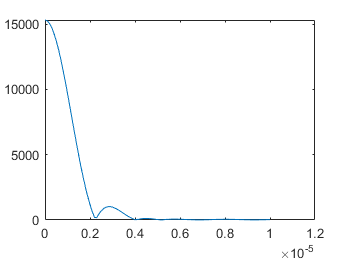

plot(0:1e-7:1e-5,U2)

function U2=U_m(Nm,k,Am,q,am,rm,R)
%以环带模型计算每环带的谱,记得考略环带模型的限制条件,以及后续可能需要评估一下精度误差
H0=(q^2+R.^2+rm^2).^0.5;
U2=Nm*k*Am*q*am^2./H0.^2.*besselj(1,k*am*rm./H0)./(k*am*rm./H0).*exp(1j*k*H0).*besselj(0,k*R*rm./H0);
end